# Lineáris Regresszió

Importáljuk be a 'weight-height.csv' fájlt, amely 10,000 megfigyelést tartalmaz 5,000 férfi és 5,000 nő esetén a súlyuk ( **weight** ~pounds) és magasságuk ( **height** ~inches) szerint. Váltsuk át a mértékeket *kg-*ba és *cm-*be.

data = readtable("weight-height.csv");
h = data.Height*2.54;
w = data.Weight*0.45;

Vizsgáljuk meg grafikusan a kapcsolatot a magasság és súly között. Számoljuk ki a korrelációs együtthatót.

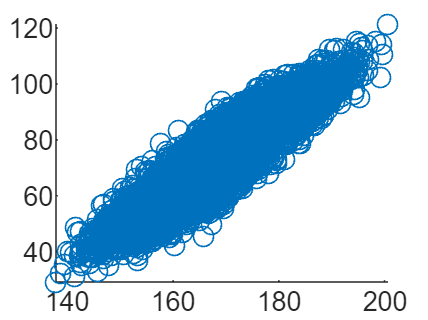

scatter(h,w)

corr(h,w)

ans = 0.9248

A következő modell paramtéereit szeretnénk becsülni:


$$\text{Súly = $\beta_0$ + $\beta_1$\cdot Magasság}$$


Ábrázoljuk a pontokat a regressziós egyenessel és a 95%-os konfidencia határokkal.

linmod = fitlm(h,w,'linear')

linmod = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE         tStat     pValue
                   ________    _________    _______    ______

    (Intercept)    -157.83       0.95017    -166.11      0   
    x1              1.3672     0.0056271     242.97      0   


Number of observations: 10000, Error degrees of freedom: 9998
Root Mean Squared Error: 5.5
R-squared: 0.855,  Adjusted R-Squared: 0.855
F-statistic vs. constant model: 5.9e+04, p-value = 0

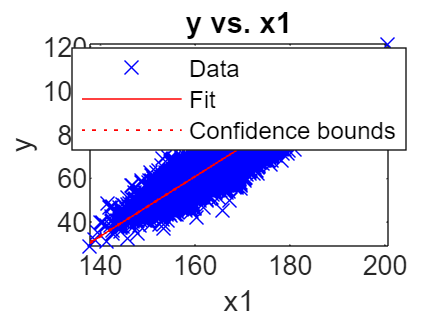

plot(linmod)

Használjon 95%-os kofidencia intervallumot a saját magasságára (cm).

[y ci] = predict(linmod, 198,'Prediction', 'observation','Alpha',0.01)

y = 112.8810

ci =    98.7069  127.0551


Ábrázolja a 99%-os kofidencia intervallumot a megfigyelésekre!

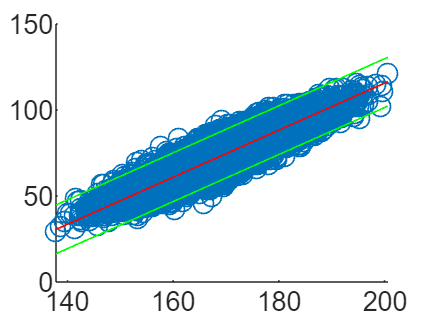

scatter(h,w)
x = linspace(min(h),max(h));
[y ci] = predict(linmod, x','Prediction', 'observation', ...
    'Alpha',0.01);
hold on
plot(x,y,'r',x,ci(:,1),'g',x,ci(:,2),'g')
hold off

Vegyen 100 véletleszerű megfigyelést a teljes adathalmazból. Hajtsa végre rajta az előzőeket.

rng(1); ind = randi(10000,100,1);
subdata = data(ind,:);
sh = subdata.Height*2.54;
sw = subdata.Weight*.45;
sublm = fitlm(sh,sw,'linear')

sublm = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)     -147.7       9.6739    -15.268    1.1801e-27
    x1               1.307     0.056897     22.971    3.0974e-41


Number of observations: 100, Error degrees of freedom: 98
Root Mean Squared Error: 5.86
R-squared: 0.843,  Adjusted R-Squared: 0.842
F-statistic vs. constant model: 528, p-value = 3.1e-41

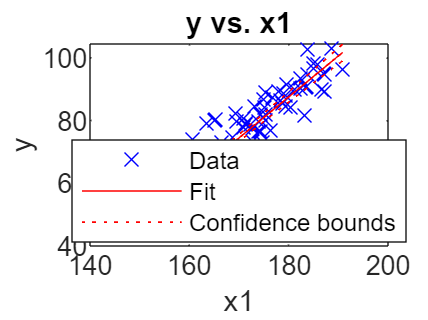

plot(sublm)

## Feladat

- Hasonlítsuk össze a nemek szerint a korrelációkat. 

- Használja csak a saját neméhez tartozó modellt. Hasonlítsa össze a modell paramétereket.